#### Homework 6, Problem 3

% David Lim
% A16398479
% 03/06/25
clear

#### Step 1: State space representation

% Define parameters
N = 40;
T = 10;
mu = 0.1;
L = 5;
c = L^2*mu/(N^2*T);

% Construct A matrix
A = zeros(2*N);
for i = 1:N  % string element index
    k = 2*i-1;  % odd number index
    A(k,k+1) = 1;
    if i > 1; A(k+1,k-2) = 1/c; end
    A(k+1,k) = -2/c;
    if i < N; A(k+1,k+2) = 1/c; end
end

% Construct C matrix
C = zeros(N,2*N);
for i = 1:N
    C(i,2*i-1) = 1;
end

% Display results for publishing
A

A =            0           1           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
      -12800           0        6400           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           

C

C =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0   

eig(A)

ans = 1.0e+02 *

  -0.0000 + 1.5988i
  -0.0000 - 1.5988i
  -0.0000 + 1.5953i
  -0.0000 - 1.5953i
  -0.0000 + 1.5894i
  -0.0000 - 1.5894i
   0.0000 + 1.5812i
   0.0000 - 1.5812i
  -0.0000 + 1.5707i
  -0.0000 - 1.5707i


#### Step 2: Modal decomposition

% IMPORTANT (excerpt from MATLAB documentation, learned the hard way):
% By default eig does not always return the eigenvalues and eigenvectors in
% sorted order. Use the sort function to put the eigenvalues in ascending
% order and reorder the corresponding eigenvectors.

[V,D] = eig(A);  % diagonalizes A
% WRONG (assumed eig always ordered eigenvalues):
% V = fliplr(V);  % reorders eigenvalues from least to greatest magnitude
% D = rot90(D,2);  % reorders eigenvectors
% RIGHT (copied from MATLAB documentation):
[d,ind] = sort(diag(D));
D = D(ind,ind);
V = V(:,ind);

X = zeros(size(V));  % preallocate transformation matrix
Anew = zeros(size(D));  % preallocate block diagonal matrix

% Construct block diagonal matrix Anew
for i = 1:N
    k = 2*i-1;

    p1 = (V(:,k)+V(:,k+1))/2;
    p2 = (V(:,k)-V(:,k+1))/2j;
    a1 = real(D(k,k));
    b1 = imag(D(k,k));

    X(:,k:k+1) = [p1 p2];
    Anew(k:k+1,k:k+1) = [a1 b1; -b1 a1];
end

% Display results for publishing
X

X =     0.0000    0.0027    0.0000   -0.0027    0.0000    0.0027   -0.0000    0.0027   -0.0000    0.0027    0.0000   -0.0027    0.0000    0.0027   -0.0000    0.0026    0.0000    0.0026   -0.0000    0.0026    0.0000   -0.0025   -0.0000   -0.0025    0.0000   -0.0024    0.0000    0.0024   -0.0000   -0.0023   -0.0000    0.0023    0.0000    0.0022   -0.0000    0.0021    0.0000   -0.0021   -0.0000   -0.0020    0.0000    0.0019    0.0000   -0.0018   -0.0000   -0.0018   -0.0000    0.0017   -0.0000   -0.0016
    0.0167    0.0000   -0.0336   -0.0000    0.0502   -0.0000    0.0666    0.0000    0.0825   -0.0000   -0.0980   -0.0000    0.1128   -0.0000    0.1270    0.0000    0.1405   -0.0000    0.1531    0.0000   -0.1649   -0.0000   -0.1756    0.0000   -0.1854   -0.0000    0.1940    0.0000   -0.2015    0.0000    0.2079    0.0000    0.2130    0.0000    0.2168    0.0000   -0.2194   -0.0000   -0.2207         0    0.2207   -0.0000   -0.2194   -0.0000   -0.2168    0.0000    0.2130    0.0000   -0.2079    0

Anew

Anew =    -0.0000   -6.1284         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    6.1284   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Cnew = C*X

Cnew =     0.0000    0.0027    0.0000   -0.0027    0.0000    0.0027   -0.0000    0.0027   -0.0000    0.0027    0.0000   -0.0027    0.0000    0.0027   -0.0000    0.0026    0.0000    0.0026   -0.0000    0.0026    0.0000   -0.0025   -0.0000   -0.0025    0.0000   -0.0024    0.0000    0.0024   -0.0000   -0.0023   -0.0000    0.0023    0.0000    0.0022   -0.0000    0.0021    0.0000   -0.0021   -0.0000   -0.0020    0.0000    0.0019    0.0000   -0.0018   -0.0000   -0.0018   -0.0000    0.0017   -0.0000   -0.0016
    0.0000    0.0054    0.0000   -0.0054    0.0000    0.0053   -0.0000    0.0052   -0.0000    0.0050   -0.0000   -0.0048    0.0000    0.0046   -0.0000    0.0043    0.0000    0.0040   -0.0000    0.0037    0.0000   -0.0034   -0.0000   -0.0030    0.0000   -0.0026    0.0000    0.0023    0.0000   -0.0019    0.0000    0.0015   -0.0000    0.0012    0.0000    0.0008    0.0000   -0.0005   -0.0000   -0.0002   -0.0000   -0.0001   -0.0000    0.0004    0.0000    0.0007    0.0000   -0.0009    0.0000  

#### Step 3: First mode

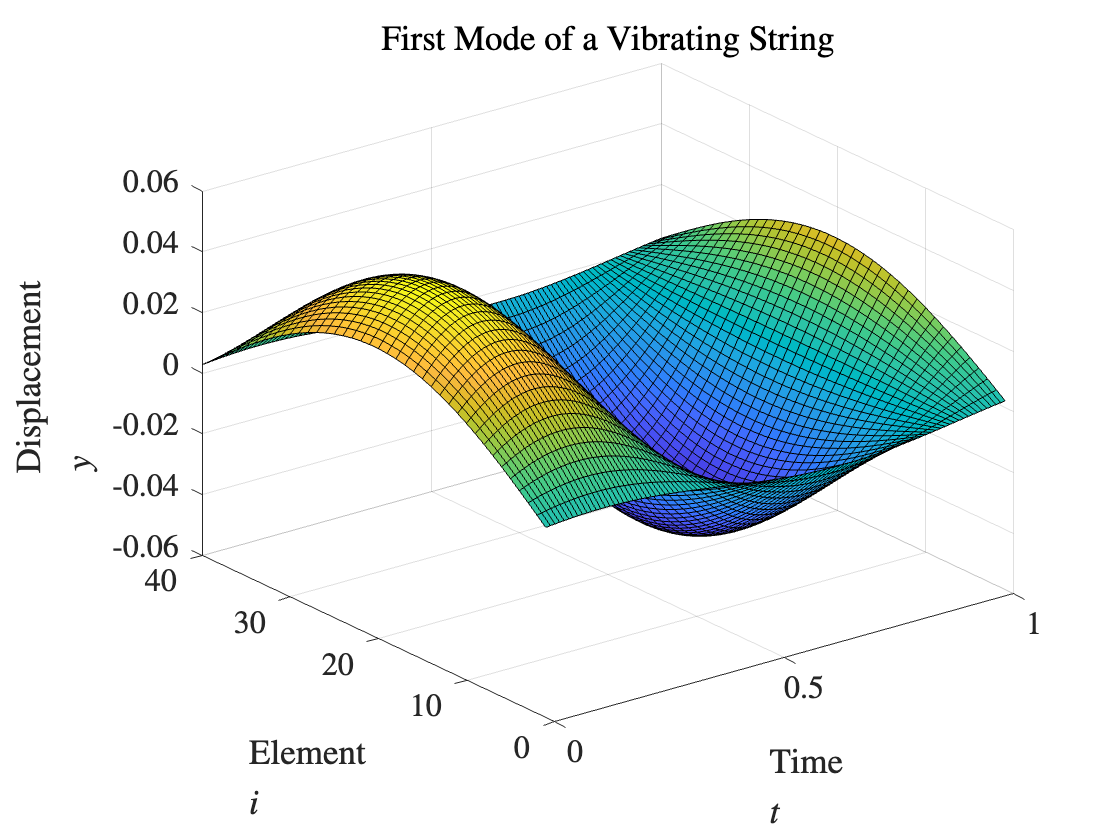

q01 = zeros(2*N,1);
q01(1:2) = [1;1];  % initial condition

t = 0:0.01:1;
M = length(t); 
q1 = zeros(2*N,M);
q1(:,1) = q01;
for j = 2:M
    q1(:,j) = expm(Anew*t(j))*q1(:,1);
end
y1 = Cnew*q1;

figure(1)
surf(t,1:N,y1);
xlabel('Time $$t$$','Interpreter','latex')
ylabel('Element $$i$$','Interpreter','latex')
zlabel('Displacement $$y$$','Interpreter','latex')
title('First Mode of a Vibrating String','Interpreter','latex')
set(gca,'FontSize',16,'TickLabelInterpreter','latex')

#### Step 4: Second mode

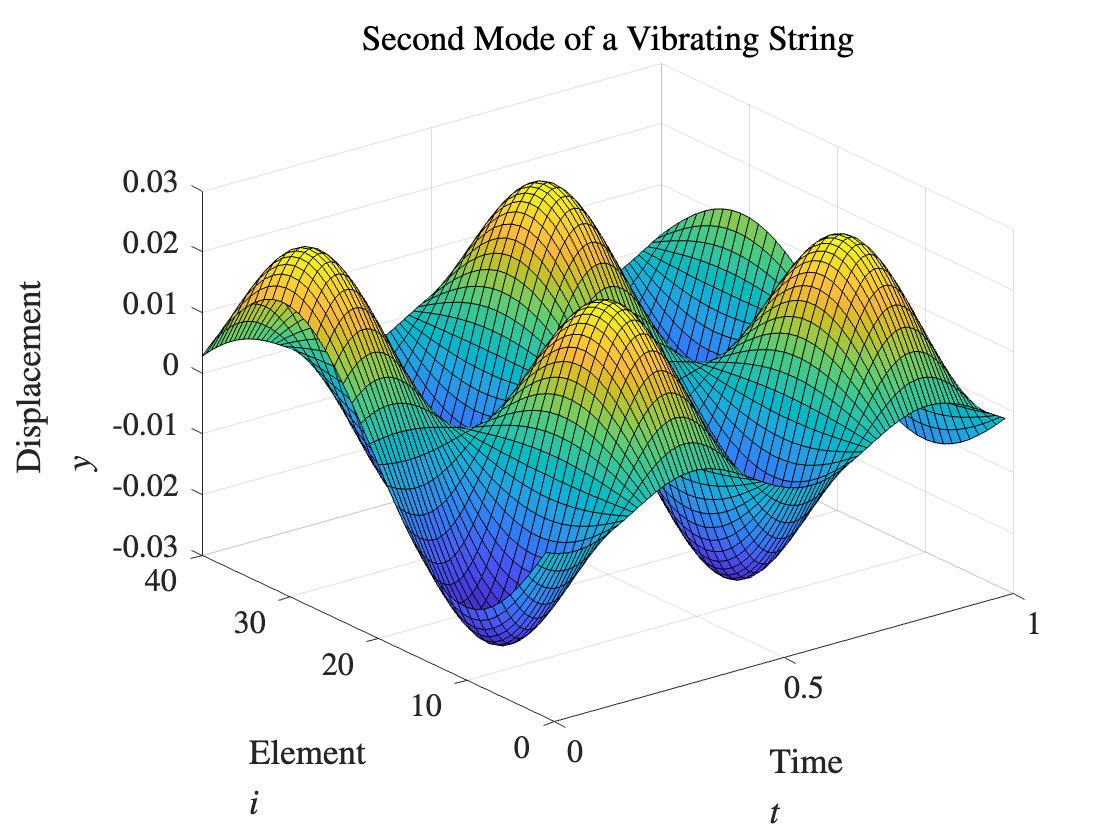

q02 = zeros(2*N,1);
q02(3:4) = [1;1];  % initial condition

q2 = zeros(2*N,M);
q2(:,1) = q02;
for j = 2:M
    q2(:,j) = expm(Anew*t(j))*q2(:,1);
end
y2 = Cnew*q2;

figure(2)
surf(t,1:N,y2);
xlabel('Time $$t$$','Interpreter','latex')
ylabel('Element $$i$$','Interpreter','latex')
zlabel('Displacement $$y$$','Interpreter','latex')
title('Second Mode of a Vibrating String','Interpreter','latex')
set(gca,'FontSize',16,'TickLabelInterpreter','latex')

#### Step 5: Third mode

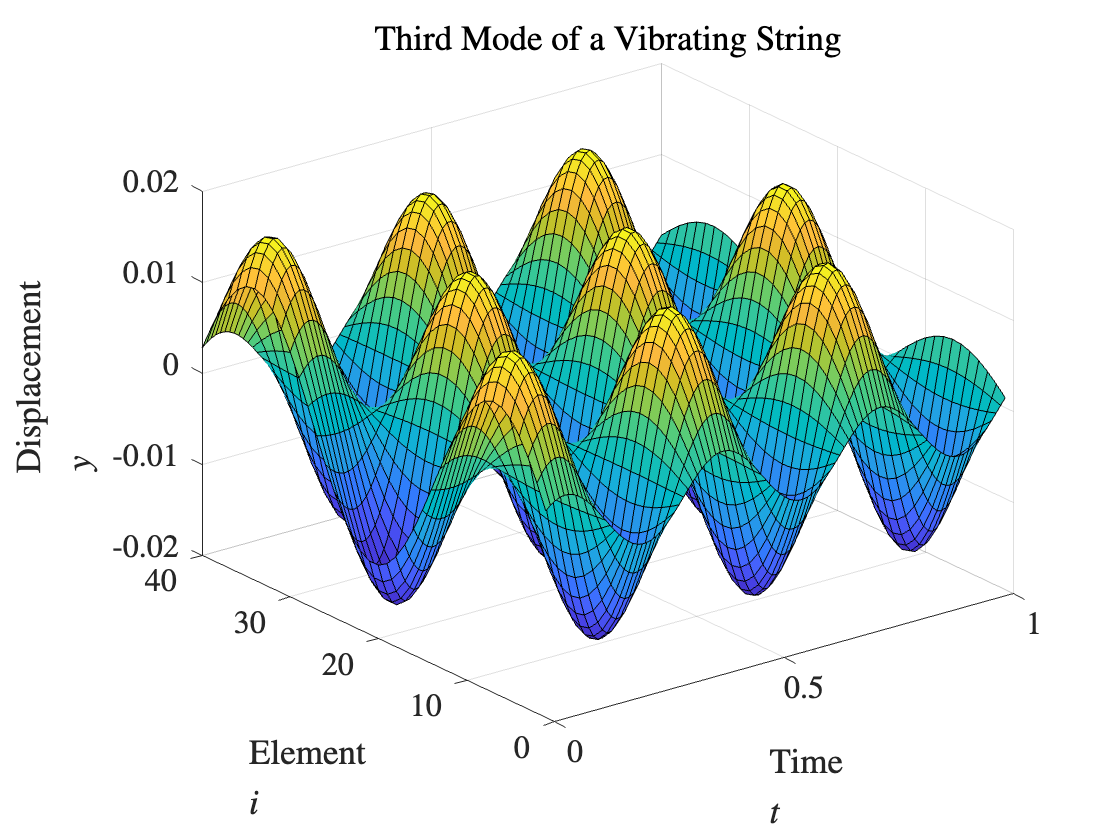

q03 = zeros(2*N,1);
q03(5:6) = [1;1];  % initial condition

q3 = zeros(2*N,M);
q3(:,1) = q03;
for j = 2:M
    q3(:,j) = expm(Anew*t(j))*q3(:,1);
end
y3 = Cnew*q3;

figure(3)
surf(t,1:N,y3);
xlabel('Time $$t$$','Interpreter','latex')
ylabel('Element $$i$$','Interpreter','latex')
zlabel('Displacement $$y$$','Interpreter','latex')
title('Third Mode of a Vibrating String','Interpreter','latex')
set(gca,'FontSize',16,'TickLabelInterpreter','latex')